## Problem 4.15 

    *ECG data are often used to determine the heart rate by measuring the time interval*

    *between the peaks that occur in each cycle known as the R wave. To determine the*

    *position of this peak accurately, ECG data are first prefiltered with a bandpass filter*

    *that enhances the R wave and the two small negative peaks on either side, the Q and S*

    *wave. The three waves together are termed the QRS complex. Load file ECG_noise.*

    *mat, which contains 10 s of noisy ECG data in variable ecg. Filter the data with a*

    *65-coefficient FIR bandpass filter to best enhance the R-wave peaks. Use the tapering*

    *window of your choice. (Note that it is not possible to eliminate all the noise, just*

    *improve the identification of the peaks.) Determine the low and high cutoff frequencies*

    *empirically, but they will be in the range of 4–24 Hz. The sampling frequency is*

    *250 Hz.*

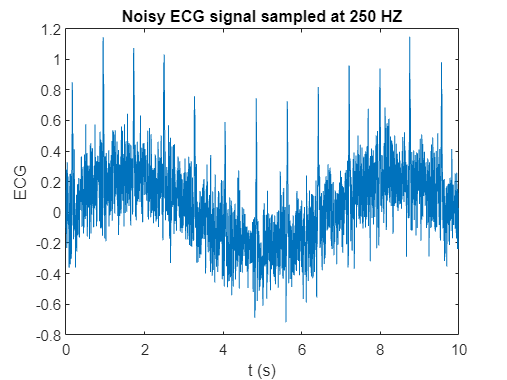

clear workspace
% loading the noisy ECG signal
load ECG_noise.mat;
N    = length(ecg); % Length of signal, no. of data points
Fs   = 250;         % Sampling frequency                    
T    = 1/Fs;        % Sampling period       
t    = (0:N-1)*T;   % Time vector

figure('Name', 'Plotting Input'), plot(t, ecg);
title("Noisy ECG signal sampled at 250 HZ")
xlabel("t (s)"), ylabel("ECG"),

% if error, check contents using [whos -file ECG_noise.mat]

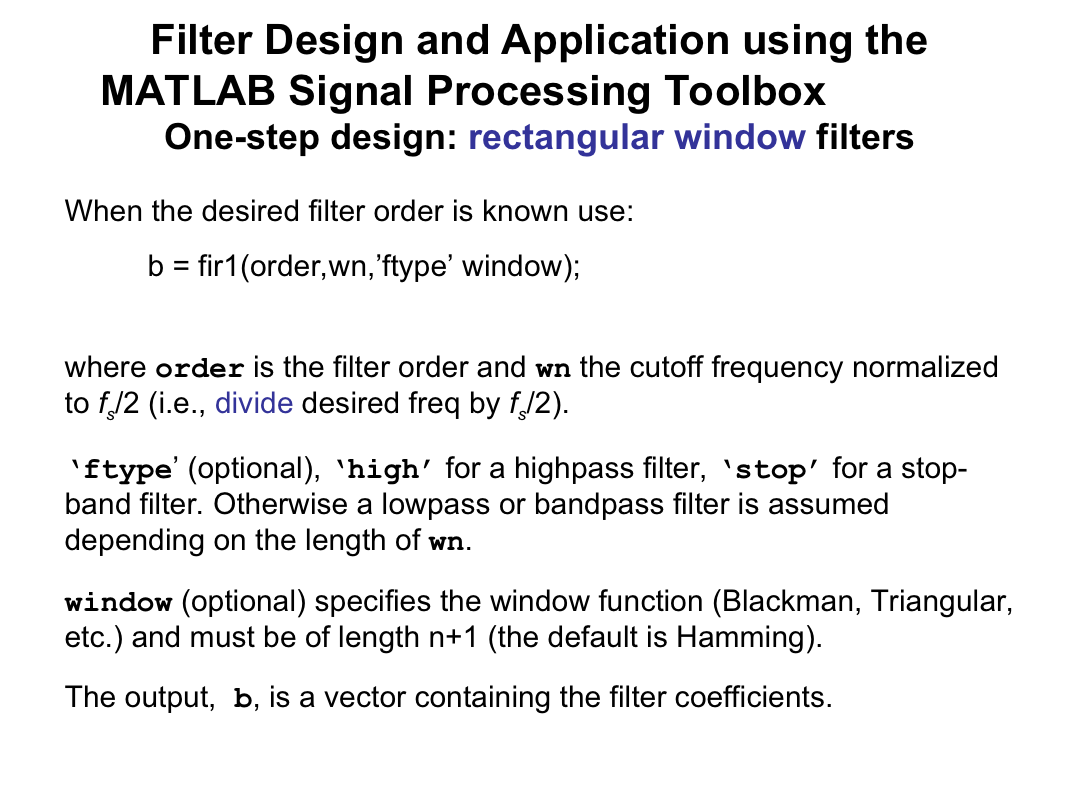

Slide 68 in "[ece 5351 lecture chapter 4 020623 PPT](https://texastechuniversity-my.sharepoint.com/:p:/g/personal/ahmed_bayoumi_ttu_edu/EW2HOY69X4BPvZ4dAsmil6IBUHjfEb7cyLlgAjqxvrYADQ?e=Y9z4pM&nav=eyJzSWQiOjI3MiwiY0lkIjowfQ)"

% define filter parameters
fband = [4 24]; %[lower upper]
fbandn = fband/(Fs/2); %normalize

% Design filter using (Parks-McClellan algorithm?least-squares
% approximation? Which?)
n = 64; % number of filter coefficients
b = fir1(n, fbandn, 'bandpass', kaiser(n+1,10));
a = 1;

The choice of window function should be based on the specific requirements of the filter design. For example, if a narrow transition width is required, the Kaiser window may be a good choice, as it provides a trade-off between mainlobe width and stopband attenuation. If a wider transition width is acceptable, a simpler window function like the Hamming or Hanning window may be sufficient.

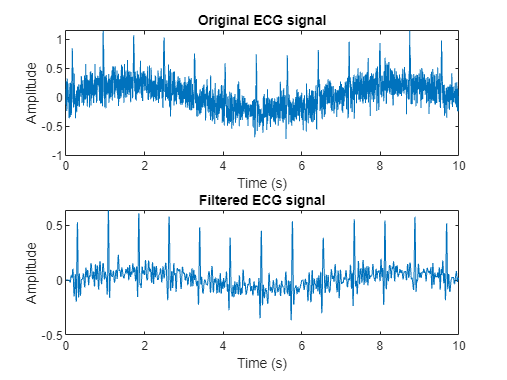

y = filter(b,1,ecg); % apply filter to ECG signal

figure('Name', 'Post Filtering');
subplot(2,1,1);
plot(t, ecg);
title('Original ECG signal');
xlabel('Time (s)');
ylabel('Amplitude');
subplot(2,1,2);
plot(t, y);
title('Filtered ECG signal');
xlabel('Time (s)');
ylabel('Amplitude');

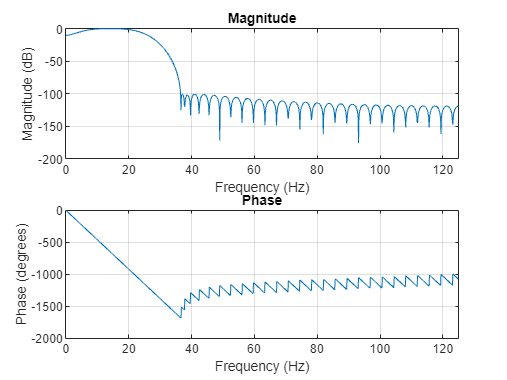


figure('Name', 'Filter Response')
freqz(b,1,1024,Fs)

## Problem 4.24:

    *This problem demonstrates a comparison of a causal and a noncausal IIR filter implementation.*

    *Load file Resp_noise1.mat containing a noisy respiration signal in*

    *variable resp_noise1. Assume a sample frequency of 125 Hz. Construct a 14thorder*

    *Butterworth filter with a cutoff frequency of 0.15 fs/2. Filter that signal using*

    *both filter and filtfilt and plot the original and both filtered signals. Plot the*

    *signals offset on the same graph to allow for easy comparison. Also plot the noise-free*

    *signal found as resp in file Resp_noise1.mat below the other signals. Note how*

    *the original signal compares with the two filtered signals, in terms of the restoration*

    *of features in the original signal and the time shift.*

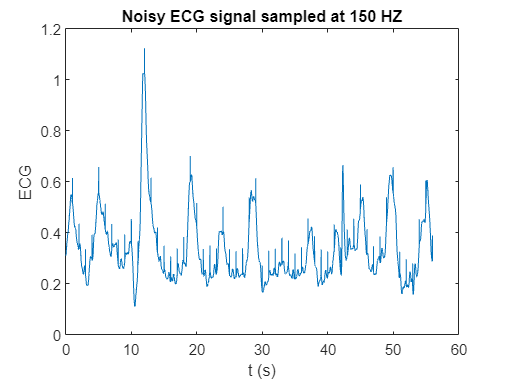

clearvars; 
load Resp_noise.mat %resp_noise(1x7001 double), fs(125);
load ('Resp_noise1.mat', 'resp') %resp(1x701 double), fs(12.5); 
%                                   this clean signal is sampled at 
%                                   a 10times slower rate; why?

T    = 1/fs;        % Sampling period       
t_resp_noise    = (0:length(resp_noise)-1)*T;   % Time vectors
t_resp          = (0:(length(resp)-1))*T*10; %multiplying by 10 
% to artifically bump up the sampling rate for visualization

figure('Name', 'Plotting Input'), plot(t_resp_noise, resp_noise);
title("Noisy ECG signal sampled at 150 HZ")
xlabel("t (s)"), ylabel("ECG"),

 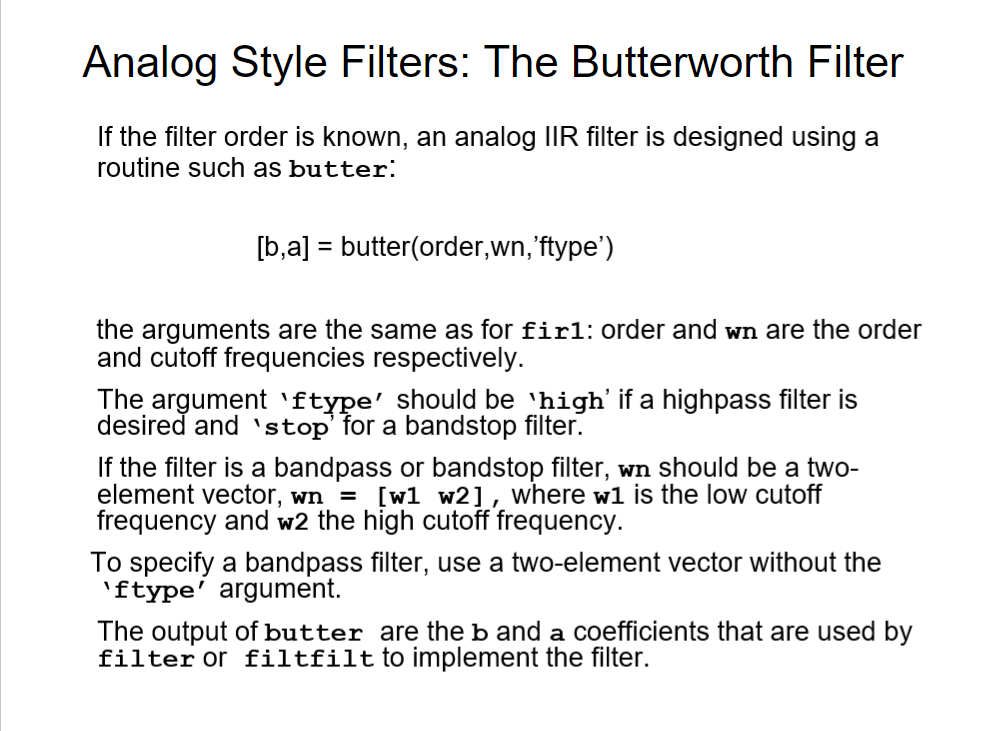

[ece 5351 lecture chapter 4 020623.ppt](https://texastechuniversity-my.sharepoint.com/:p:/g/personal/ahmed_bayoumi_ttu_edu/EW2HOY69X4BPvZ4dAsmil6IBUHjfEb7cyLlgAjqxvrYADQ?e=aCyKI9&nav=eyJzSWQiOjI3OSwiY0lkIjowfQ)

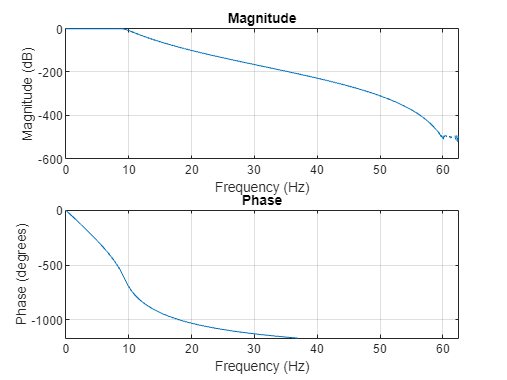

% designing butterworth filter
fc   = 0.15*fs/2;    % cutoff frequency
order= 14;

[b,a] = butter(order, fc/(fs/2));
% Plot frequency response of filter
freqz(b,a,1024,fs)

The Butterworth filter is a type of low-pass filter, but it can be use)d to design other types of filters (e.g., high-pass, band-pass, band-stop) by transforming the frequency response of the low-pass filter. The Butterworth filter has a maximally flat magnitude response in the passband, which means that it has a constant gain across the passband and the cutoff frequency. This property makes the Butterworth filter suitable for applications where a flat frequency response is desired.

The Butterworth filter is characterized by two parameters: the cutoff frequency and the filter order. The cutoff frequency is the frequency at which the filter begins to attenuate the signal. The filter order determines how steeply the filter attenuates frequencies beyond the cutoff frequency. Higher-order filters have steeper roll-off rates, but they may also introduce more phase distortion and have longer transient response times.

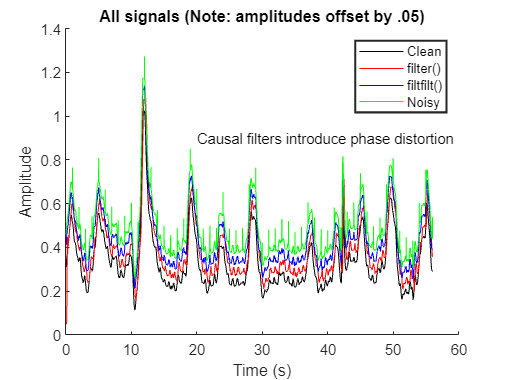

y1 = filter(b,a,resp_noise); % apply filters to signal
y2 = filtfilt(b,a,resp_noise); 

figure('Name', 'Post Filtering');
hold on
plot(t_resp, resp, 'k', t_resp_noise, (y1+0.05), 'r', t_resp_noise, (y2+0.10), 'b', t_resp_noise, (resp_noise+0.15), 'g');
text(20,0.9,'Causal filters introduce phase distortion');
legend ('Clean', 'filter()', 'filtfilt()', 'Noisy', 'LineWidth', 1.5);
title('All signals (Note: amplitudes offset by .05)');
xlabel('Time (s)');
ylabel('Amplitude');